# Generation for a virtual course and vehicle path

## Initialization

clear; close all; clc;

## Colour settings for course components 

RGB utilise the combination of 3 numerical values to define the colours. Each value can varies from 0 to 255.

grassColor = [0,193,47]; % for lawn
roadColor = [128,128,128]; % for track
centerLineColor = [255,255,255]; % for centre line
boundaryLineColor = [255,255,0]; % for boundary line for lawn and track

## Draw the circuit course and vehicle path

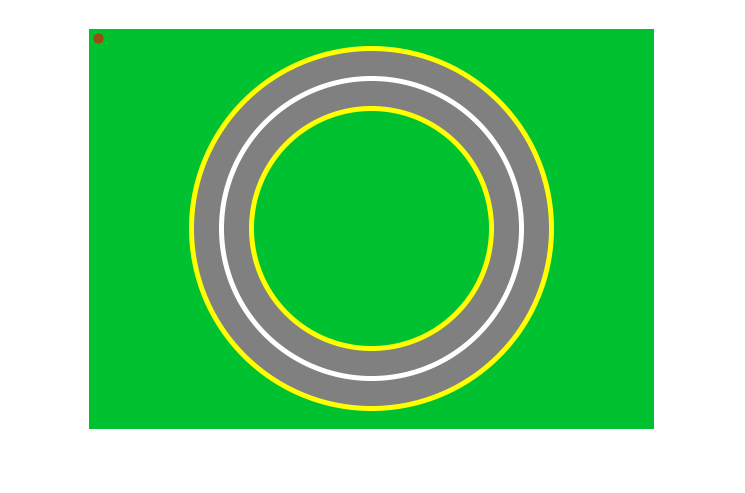

sizeMap = [400,565]; % resolution of map
centerMap = sizeMap([2,1])/2; % centre of the map
r = 150; % radius 
im = uint8(repmat(permute(grassColor,[1 3 2]),sizeMap));
im = insertShape(im,"FilledCircle",[10 10 5],"Color","red");
im = insertShape(im,"FilledCircle",[centerMap 180],...
    "Color",roadColor,"Opacity",1);
im = insertShape(im,"Circle",[centerMap 180],...
    "Color",boundaryLineColor,"Opacity",1,"LineWidth",5);
im = insertShape(im,"Circle",[centerMap r],...
    "Color",centerLineColor,"Opacity",1,"LineWidth",5);
im = insertShape(im,"FilledCircle",[centerMap 120],...
    "Color",roadColor,"Opacity",1);
im = insertShape(im,"FilledCircle",[centerMap 120],...
    "Color",grassColor,"Opacity",1,"LineWidth",5);
im = insertShape(im,"Circle",[centerMap 120],...
    "Color",boundaryLineColor,"Opacity",1,"LineWidth",5);
figure;
imshow(im);

proj = currentProject; rootfolder = proj.RootFolder;
imwrite(im,fullfile(rootfolder,'scene','texture','course.png')); % generating the image

## **Generation of vehicle path**

Definition of the global and local coordinate system.

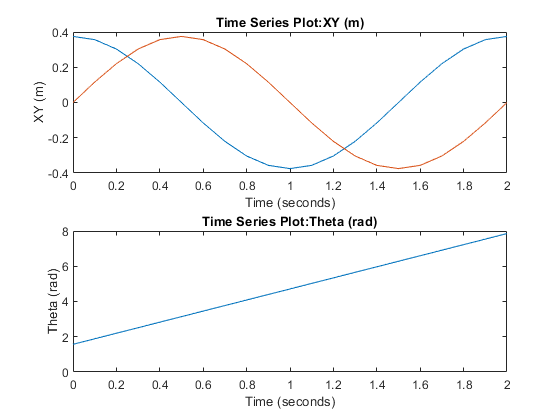

% Actual size of map
sizeMapReal = [1,1.4143];

% Sampling frequency 
fs = 0.1;

% Timestamp for ending the simulation.
Tf = 2;

% Timestamp vector
time = (0:fs:Tf)';

% Setting frequency for the vehicle to complete one round on the circuit course.  
f = 1/Tf;

% Defining an angle of the track position on the circuit course 
angles = 2*pi*f*time;

% Coordinates of the vehicle
trajXY = sizeMapReal(1)/sizeMap(1)*r*[cos(angles) sin(angles)];

% The angle of x-axis on the moving coordinate system of the vehicle with respect to the Global coordinate system.
% The x-axis of moving coordinate system is a tangential direction of the circle.


% 車両進行方向をX軸としたときのワールド座標系との角度(円の接線方向になるため +90度)
trajTheta = angles + pi/2;

% Convert array data into timeseries data, this will be used in Simulink
tsXY = timeseries(trajXY,time,'Name','XY (m)');
tsTheta = timeseries(trajTheta,time,'Name','Theta (rad)');

figure;
subplot(2,1,1);
plot(tsXY);
subplot(2,1,2);
plot(tsTheta);

## Random change of the vehicle path

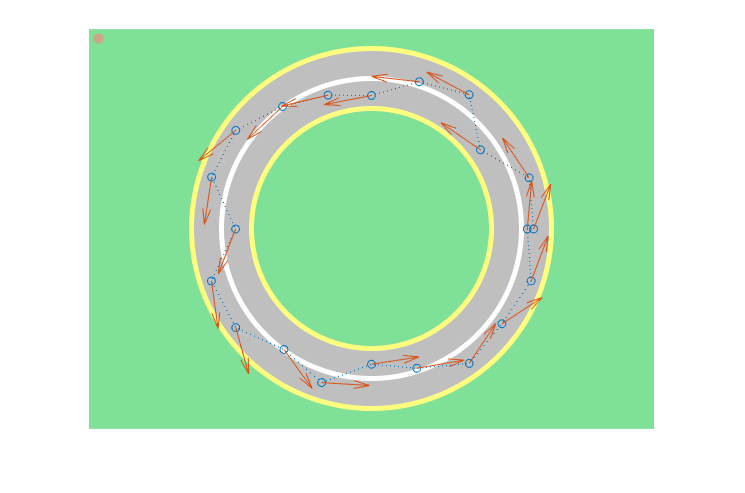

% Fixing the seed of random number for repetitive execution of the code. 
rng('default');

lenTraj = size(trajXY,1);

% lateral movement of the vehicle due to random number.
randXYTrain = 0.05*(rand(lenTraj,1)-0.5)*2.*[cos(angles) sin(angles)];
trajXYTrain = trajXY + randXYTrain;

% random change of vehicle direction based on the random number. 
randThetaTrain = pi/8*(rand(lenTraj,1)-0.5)*2;
trajThetaTrain = trajTheta+randThetaTrain;

figure;
imshow(im,'XData',[-1.4143/2 1.4143/2],'YData',[-0.5 0.5]);
alpha 0.5;
hold on;
plot(trajXYTrain(:,1),-trajXYTrain(:,2),'o:');
quiver(trajXYTrain(:,1),-trajXYTrain(:,2),...
    cos(trajThetaTrain),-sin(trajThetaTrain),0.5);

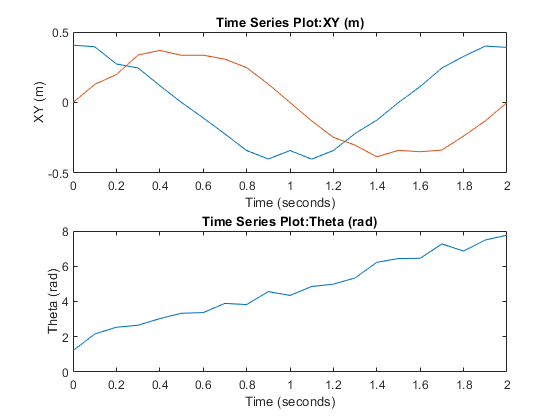


% Convert array data  into timeseries data, this will be used in Simulink
tsXYTrain = timeseries(trajXYTrain,time,'Name','XY (m)');
tsThetaTrain = timeseries(trajThetaTrain,time,'Name','Theta (rad)');

figure;
subplot(2,1,1);
plot(tsXYTrain);
subplot(2,1,2);
plot(tsThetaTrain);

**Saving the generated data**

% Saving the path into mat-file.
save('trainTrajectory.mat','tsXYTrain','tsThetaTrain');

## Generate video for training in 3-D environment

Open a Simulink model to generate dataset

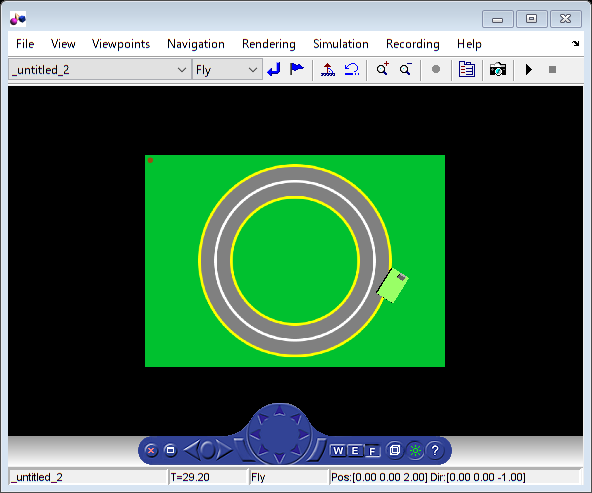

open_system('dataset_generator');

1.Run the simulation by clicking the green triangle button so that a video file (`robotTrain.avi`) is generated.

## Next step

Open [annotateVideo.mlx](matlab:open('annotateVideo.mlx')) and annotate the target positions.

## [Return to menu](matlab:open('workshopMenu.mlx'))

*Copyright 2020 The MathWorks, Inc.*